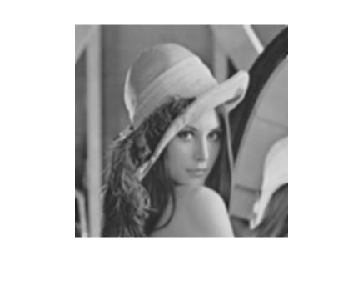

img=rgb2gray(imread('girl.jpg'));
imshow(img)

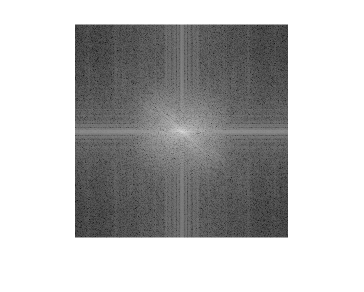

[x y]=size(img);

imf=fftshift(fft2(img));
fftshow(imf)

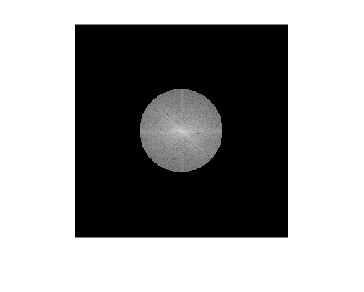


[a,b]=meshgrid(-127:128,-127:128);
z=sqrt(a.^2+b.^2);
c=(z<50);
lp=imf.*c;
fftshow(lp)

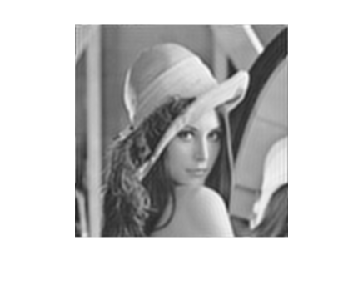


ilp=ifft2(lp);
fftshow(ilp,'abs')